# Final Project

## Paul Keene, Erica Lin

Dataset: Steinmetz, Zatka-Haas, Carandini & Harris 2019

## Setup

%set project directory (will need to change on different machine)
projDir = pwd;

%get session IDs and number
[sessionNames,nsesh] = getSessionNames(projDir);

%load the data from the raw files
[beh,eye] = loadData(sessionNames,nsesh,projDir);
load('sorted_data/neural/MOpspikes.mat'); %we used the preprocessing scripts indexClusters and selectClusters to make this


% load paths for functions
visualization_path = [pwd,'/visualize']; 
addpath(visualization_path);
analysis_path = [pwd,'/analysis']; 
addpath(analysis_path);
helper_path = [pwd,'/helpers'];
addpath(helper_path);
%Paul = 100%

## Visualization

Find the Fano Factor of 50 ms before audio go-cue, 50 ms after audio go-cue, 50 ms before visual go-cue, and 50 ms after visual go-cue.

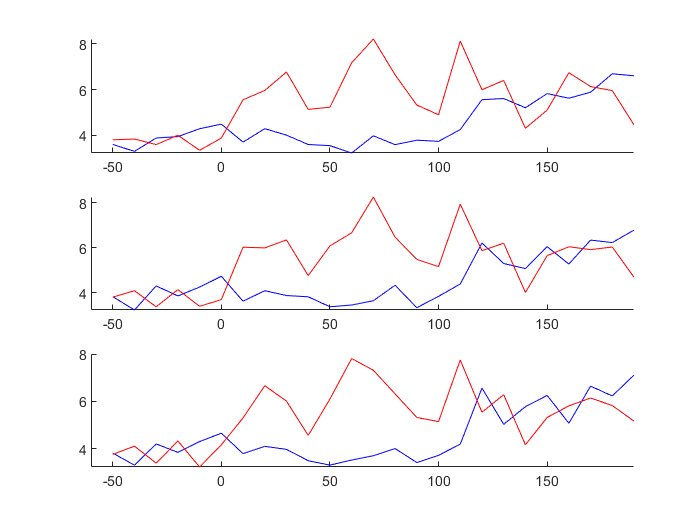

Fano Factor of spike count in MOs is always higher (relatively higher spike count variability)after stimulus / go cue / response than before.
Fano Factor of spike count in MOs is lowest overall after response -- there is relatively lower spike count variability after response.

% motor neuron activity during response to left vs right vs neutral trials
raster_subject1_directional(beh, spikes)
%Erica = 100%

% response times for stimulus of high, medium, and no difference between right and left
response_times_contrast(beh, spikes)

Response time to left stimuli encoded by left-tuned MOs neuron spike rate 50 ms before audio go-cue, 50 ms after stimulus 50 ms before visual go-cue, and 50 ms after go-cue 50 ms before response, and 50 ms after response.

Error using zeros
Requested 5399389x342x25 (344.0GB) array exceeds maximum array size preference. Creation of arrays greater than this limit may take a long time and cause MATLAB to become unresponsive.

Error in encoding_response_time (line 24)
spikeCounts_stim = zeros([nunits,num_trials,nwindows]);

Related documentation

%Erica = 100%

% average spike counts during stimulus times for motor and visual neurons
psth_avg_spike_count(beh, spikes)
%Erica = 80, Paul = 20%

% visualize gaze after stimulus appears
gaze_tracking() 

reduce dimensionality and examine what low d state best captures the activity of the neurons in MOp

error grows after 80

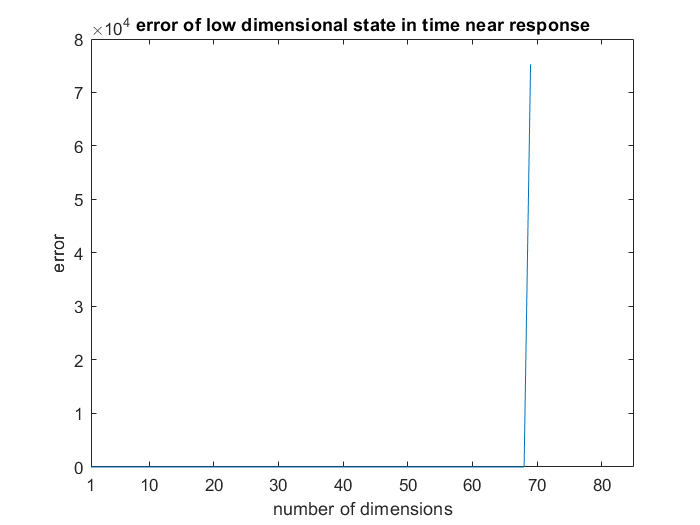

print('gaze_track','-dpng');

fprintf('we see that the subjects eyes are drawn towards the stimuli with the higher contrast')
fprintf('this implies attentional capture by the stimulus, as well as sucessful stimulus discrimination')
%Paul = 100%

% visualize wheel position during trial
wheel_position()
print('wheelpos','-dpng');
fprintf('we see that wheel position decreases for rightward trials, which indicates a right turn, and increases for left trials, which indicates a left turn')
fprintf('this implies that the mouse could successfully manipulate the response apparatus')
%Paul = 100%

%histogram of accuracy sorted by delay interval
accuracy_v_delay()
print('acc_delay','-dpng');
fprintf('We see a decrease in the number of inaccurate responses for longer delay periods. CIs calculated with bootstraps')
%Paul = 100%

## Analysis

% Spike train variability for MOs 50ms 
% before / after 
% stimulus / go cue / response
load('sorted_data/neural/MOpspike_pca.mat');
[FF_stim,FF_cue,FF_resp] = spike_train_variability(beh, spikes);
fprintf('for the example neuron, which was tuned to left stimuli, the fano factor was was roughly equal until about 50 ms after stimulus presentation, at which point it began to diverge, with higher FF for right trials')
fprintf('This makes sense, as the neuron is tuned to leftward stimuli, and so there should be less variance for those trials as opposed to rightward trials.')
%Erica = 90% Paul = 10%

% Encoder for response time on MOs spike rates
encoding_response_time(beh, spikes)
%Erica = 100%

% Classifiers for response speed on MOs spike counts during response
classify_response_speed(beh, spikes)
%Erica = 100%

%linearly reduce dimensionality
load('sorted_data/neural/MOpspike_pca.mat');
condSpikeCounts = prepDimReduct(beh,spikes);

dimensionalityReduction(condSpikeCounts);
print('dim reduct','-dpng');
load('sorted_data/neural/MOpspikes.mat');
fprintf('We observe that there are only 9 tuned neurons in this dataset, and so we would predict that the error should minimize at about 9.')
fprintf('we generally observe that the dataset is well captured by a low dimensional state roughly equal to 9, but also that error is quite large overall and that it fluctuates wildly for the first few dimensions')
fprintf('it may be the case that using too few neurons would result in only capturing one movement type, and thus all of them are necessary')

%Paul = 100%

%train auto encoder
dimsToTest = [1:55];

for i = 1:55
    [unitAutoEncoder,testData] = makeAutoencoder(condSpikeCounts,dimsToTest(i));
    mse(i) = testAutoencoder(unitAutoEncoder,testData);
end

## plot

figure;
plot([1:55],mse);
xticks([1,10,20,30,40,50,55])
xticklabels([1,10,20,30,40,50,55]);
ylabel("mean squared err");
xlabel("hidden layer size");
title("autoencoder err vs hidden layer size")
print("autoencoder_err","-dpng");
fprintf('we see that the error is roughly the same across hidden layer sizes. This would mean that a bottleneck of one vs 50 has the same ability to reconstruct the data.')
fprintf('This makes sense with our other results, as weve seen that there are only a handful of neurons tuned to the stimuli, so it might be the case that only a handful, or even just one neuron, is a good enough representation of the dataset to allow for adequete reconstruction')